% example use of plot_function

syms t real
T = 2.5;
A = [1, 1, 1]';
B = [-1, 5, 0]';

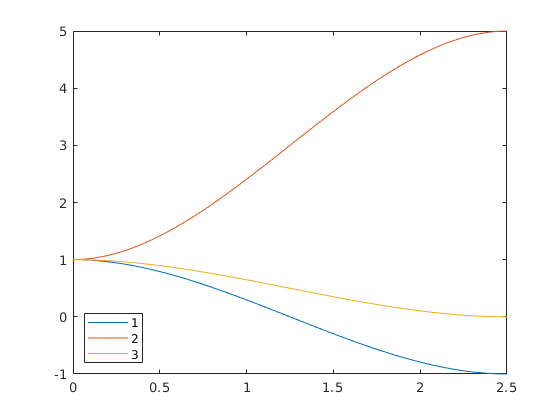

plot_function(p, t, [0, T])

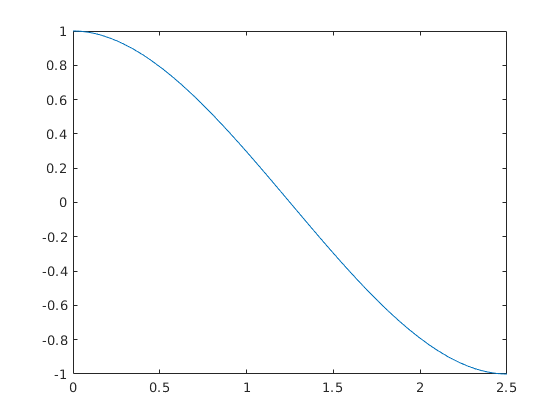

% plot single function
plot_function(p(1), t, [0, T])

% vel and acceleration

v = diff(p, t)

$$v = \left(\begin{array}{c} \frac{96\,t^{2}}{125}-\frac{48\,t}{25}\\ \frac{96\,t}{25}-\frac{192\,t^{2}}{125}\\ \frac{48\,t^{2}}{125}-\frac{24\,t}{25} \end{array}\right)$$

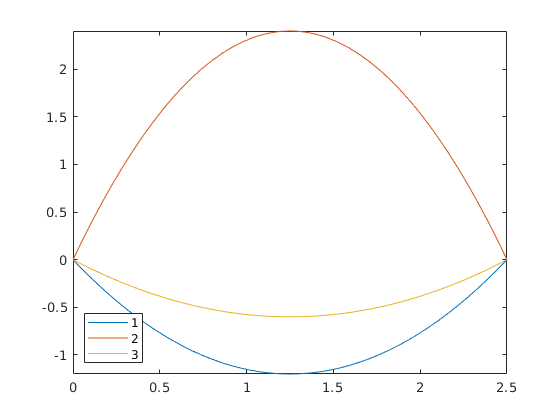

plot_function(v, t, [0, T])

v_max = norm(subs(v, {t}, {T/2}))

$$v\_max = \frac{\sqrt{189}}{5}$$

double(v_max)

ans = 2.7495

a = diff(v, t)

$$a = \left(\begin{array}{c} \frac{192\,t}{125}-\frac{48}{25}\\ \frac{96}{25}-\frac{384\,t}{125}\\ \frac{96\,t}{125}-\frac{24}{25} \end{array}\right)$$

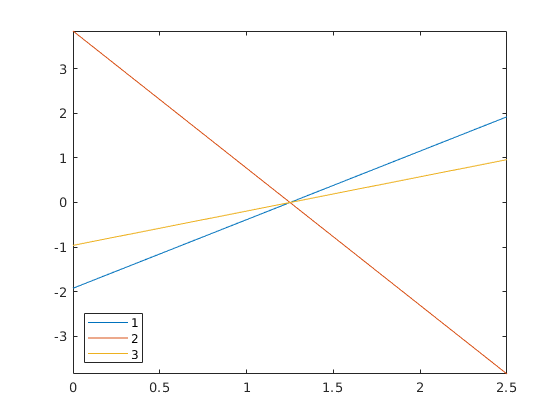

plot_function(a, t, [0, T])

a_max = norm(subs(a, {t}, {0}))

$$a\_max = \frac{\sqrt{12096}}{25}$$

double(a_max)

ans = 4.3993

% orientation
R_a =[0 1 0;
    1 0 0;
    0 0 -1]

R_a =      0     1     0
     1     0     0
     0     0    -1



R_b = [-1/sqrt(2) 0 1/sqrt(2);
    0 -1 0;
    1/sqrt(2) 0 1/sqrt(2)]

R_b =    -0.7071         0    0.7071
         0   -1.0000         0
    0.7071         0    0.7071



R = R_a'*R_b

R =          0   -1.0000         0
   -0.7071         0    0.7071
   -0.7071         0   -0.7071


[theta, r] = get_theta_r(R, 'pos')

theta = 2.5936

r =    -0.6786
    0.6786
    0.2811


theta_t = theta*t/T

$$theta\_t = \frac{5840187485854797\,t}{5629499534213120}$$

R_0 = eval(R_a*angle_axis_rotation_direct(r, subs(theta_t, {t}, {0})))

R_0 =      0     1     0
     1     0     0
     0     0    -1


R_T = eval(R_a * angle_axis_rotation_direct(r, subs(theta_t, {t}, {T})))

R_T =    -0.7071   -0.0000    0.7071
   -0.0000   -1.0000   -0.0000
    0.7071   -0.0000    0.7071


R_T_2 = eval(R_a * angle_axis_rotation_direct(r, subs(theta_t, {t}, {T/2})))

R_T_2 =    -0.0653    0.6065    0.7924
    0.6065   -0.6065    0.5142
    0.7924    0.5142   -0.3282


% angular vel and acc

theta_dot = diff(theta_t, t)

$$theta\_dot = \frac{5840187485854797}{5629499534213120}$$

omega = r*theta_dot

$$omega = \left(\begin{array}{c} -\frac{278881294557102396034760448201}{396140812571321687967719751680}\\ \frac{278881294557102396034760448201}{396140812571321687967719751680}\\ \frac{29572202111415773991920943571971}{101412048018258352119736256430080} \end{array}\right)$$

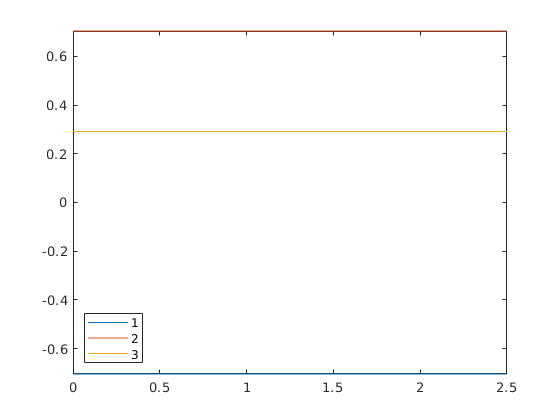

plot_function(omega, t, [0, T])

omega = eval(r*theta_dot)

omega =    -0.7040
    0.7040
    0.2916


omega_max = norm(omega)

omega_max = 1.0374

theta_dot_dot = diff(theta_dot, t)

$$theta\_dot\_dot = 0$$

omega_dot = r*theta_dot_dot

$$omega\_dot = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

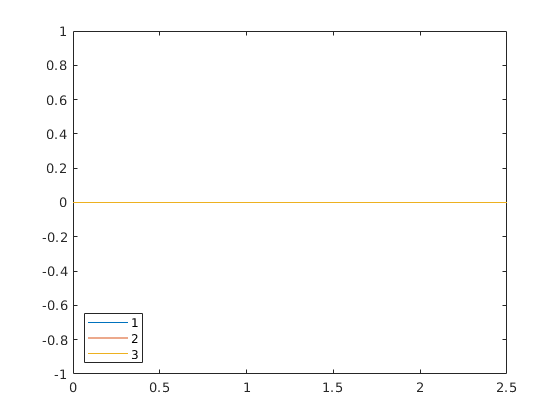

plot_function(omega_dot, t, [0, T])